# App Designer: Instrument Control over Serial (Arduino example)

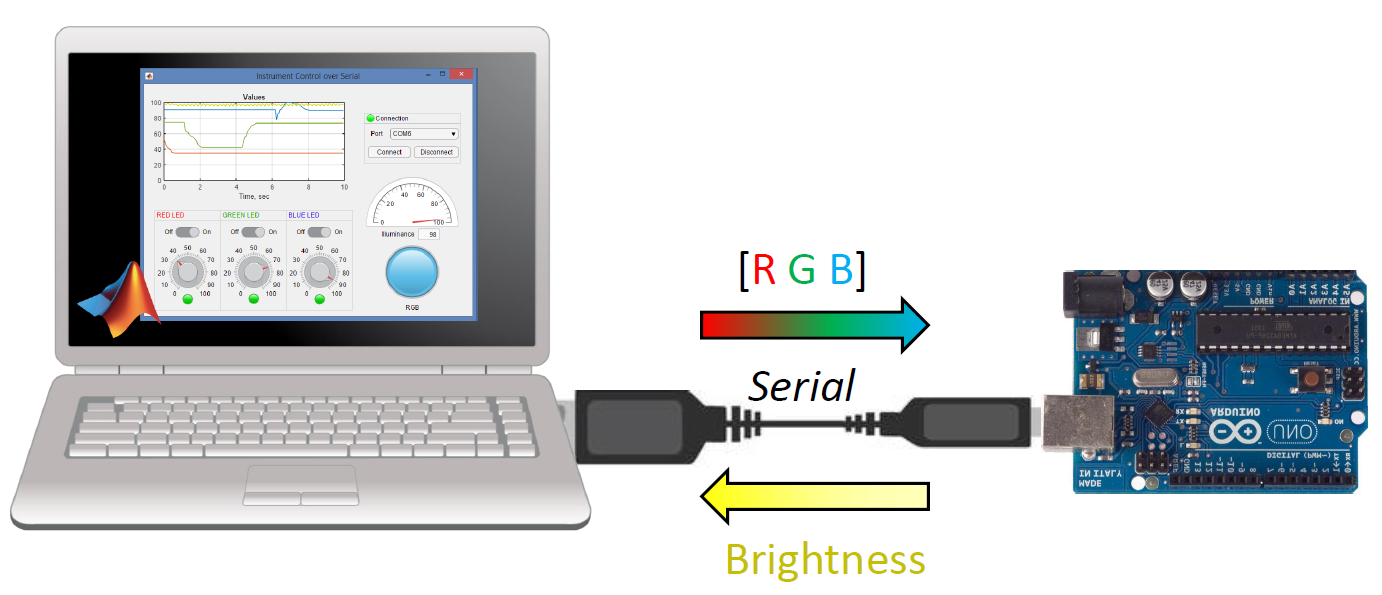

## Description

This is an example of how you can use App Designer tool to build program to control any hardware over supported protocol (i.e. serial). App Designer has visual instrumentation components (knobs, swithes, etc.) so it allows you to build interactive apps for instrument control. 

The submission contains a scheme of Arduino based simple device with RGB LED and photoelectric cell. Simulink program for Arduino is provided. 

With interactive program you can control the RGB LED color and observe illuminance level over the serial connection. If you don't have Arduino you can simulate it from Control App.

Describing video for v1.0 R2016a version (on Russian, enable auto-translate captions):

[https://youtu.be/gixP32MudA4](https://youtu.be/gixP32MudA4)

## Requirements

- MATLAB R2019a

**Recommended for better experience**

- [Instrument Control Toolbox](https://www.mathworks.com/products/instrument.html)

**Required for Arduino programming**

- [Simulink](https://www.mathworks.com/products/simulink.html)

- [Simulink Support Package for Arduino Hardware](https://www.mathworks.com/matlabcentral/fileexchange/40312)

## Start with LED Control

You can start with simplified tutorial example - LED Control. It allows you to control built-in Arduino LED attached to pin 13.

[Open LED Control](matlab:open led_doc)

## RGB Control App

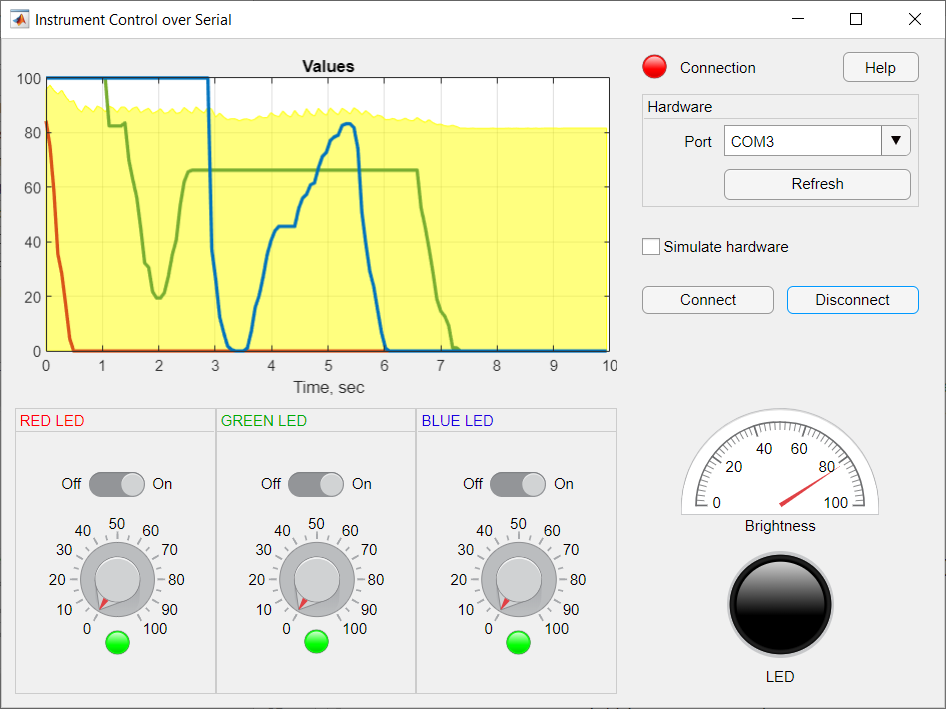

Run Control App:

rgb_control

**How to use:**

- Select or type in Arduino COM **Port **(see [how to find Arduino port](https://www.mathworks.com/help/supportpkg/arduinoio/ug/find-arduino-port-on-windows-mac-and-linux.html))

- OR check **Simulate hardware** if you don't want to use serial and only want to explore App behaviour

- Press **Connect** to open connection and start control process

- Press **Disconnect** or close the App to stop control process

When user changes states of control interface elements (knobs and swithes) appropriate callbacks write RGB values to the app internal properties. When App receives from Arduino light level data it writes light level also to the app internal properties. 

The app with a fixed time intervals when a Timer object callback fires: 

- Reads RGB and light level values from app internal properties

- Updates visual elements (plots and lamps)

- Sends RGB data to Arduino over serial

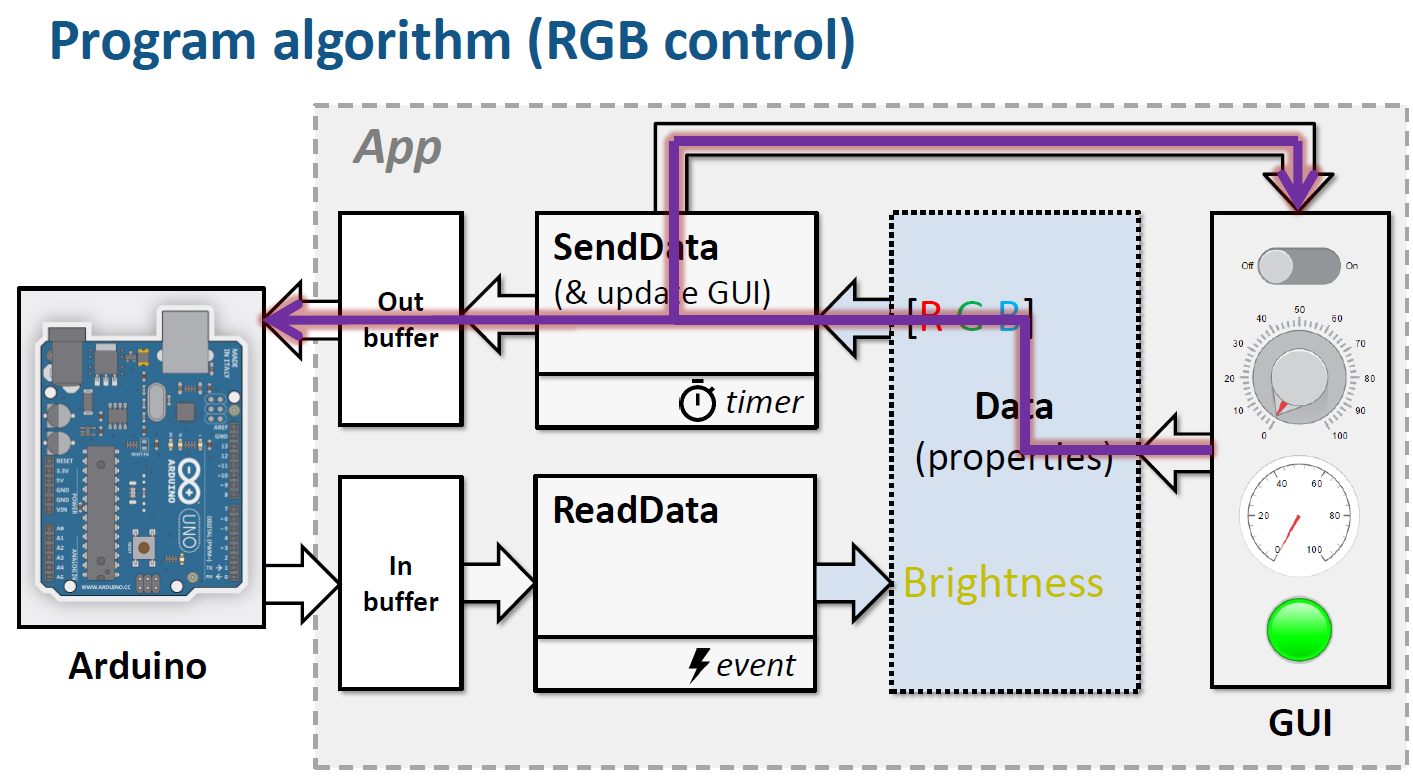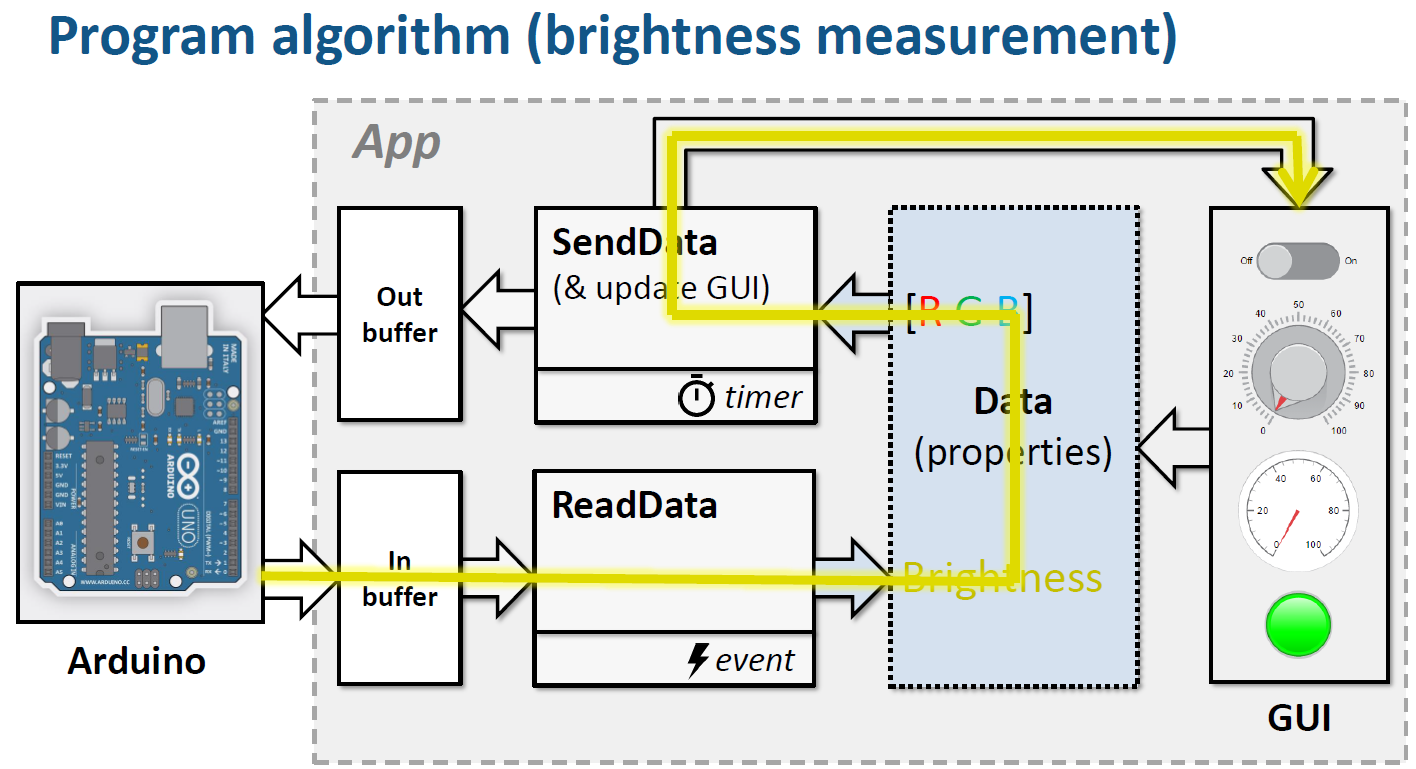

## Arduino Hardware

Connect RGB LED to Arduino as shown on the scheme

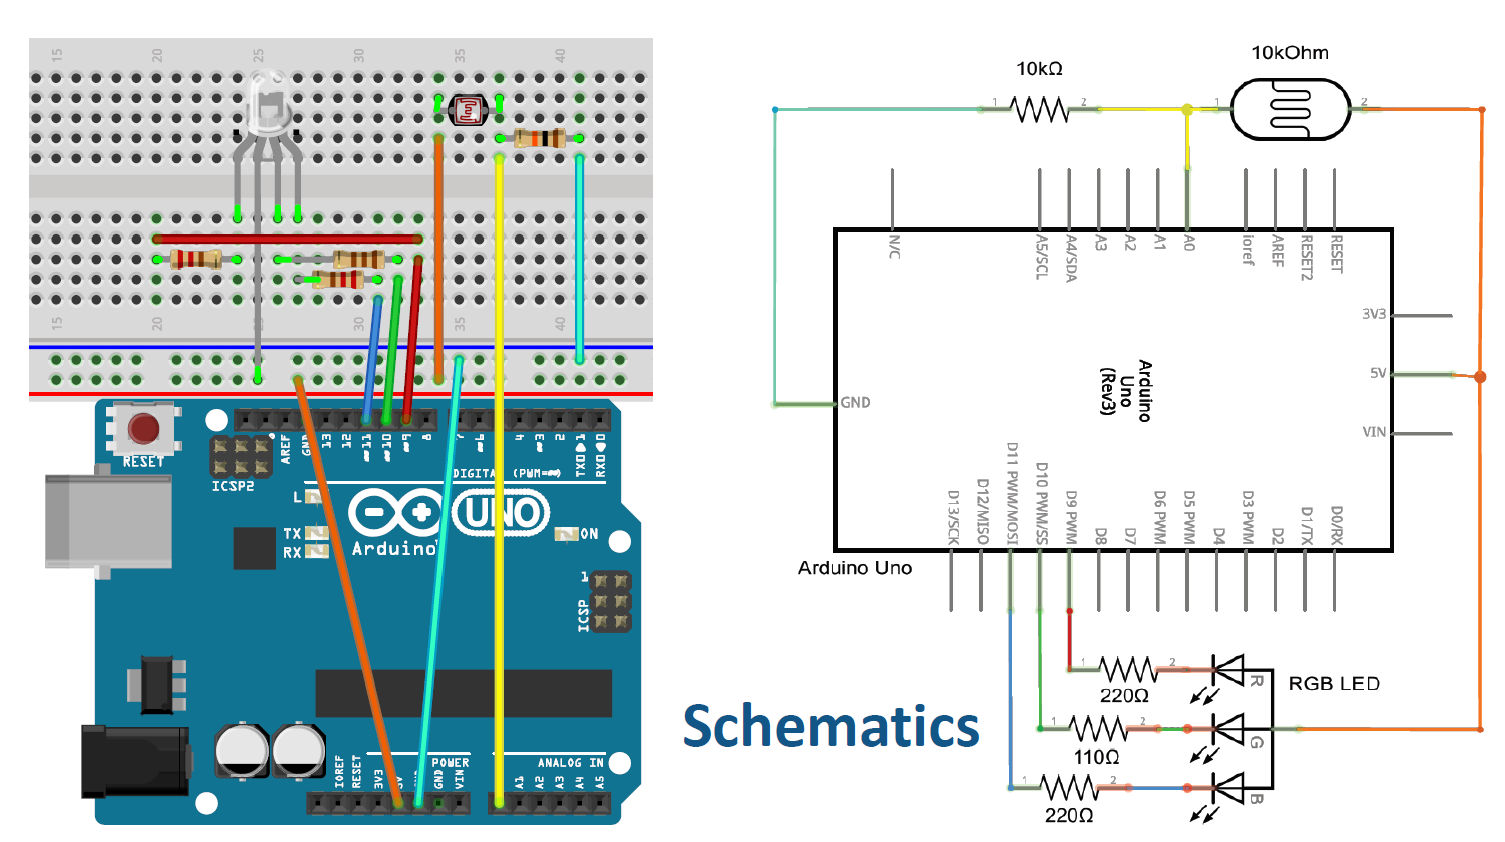

Example with DIY shield

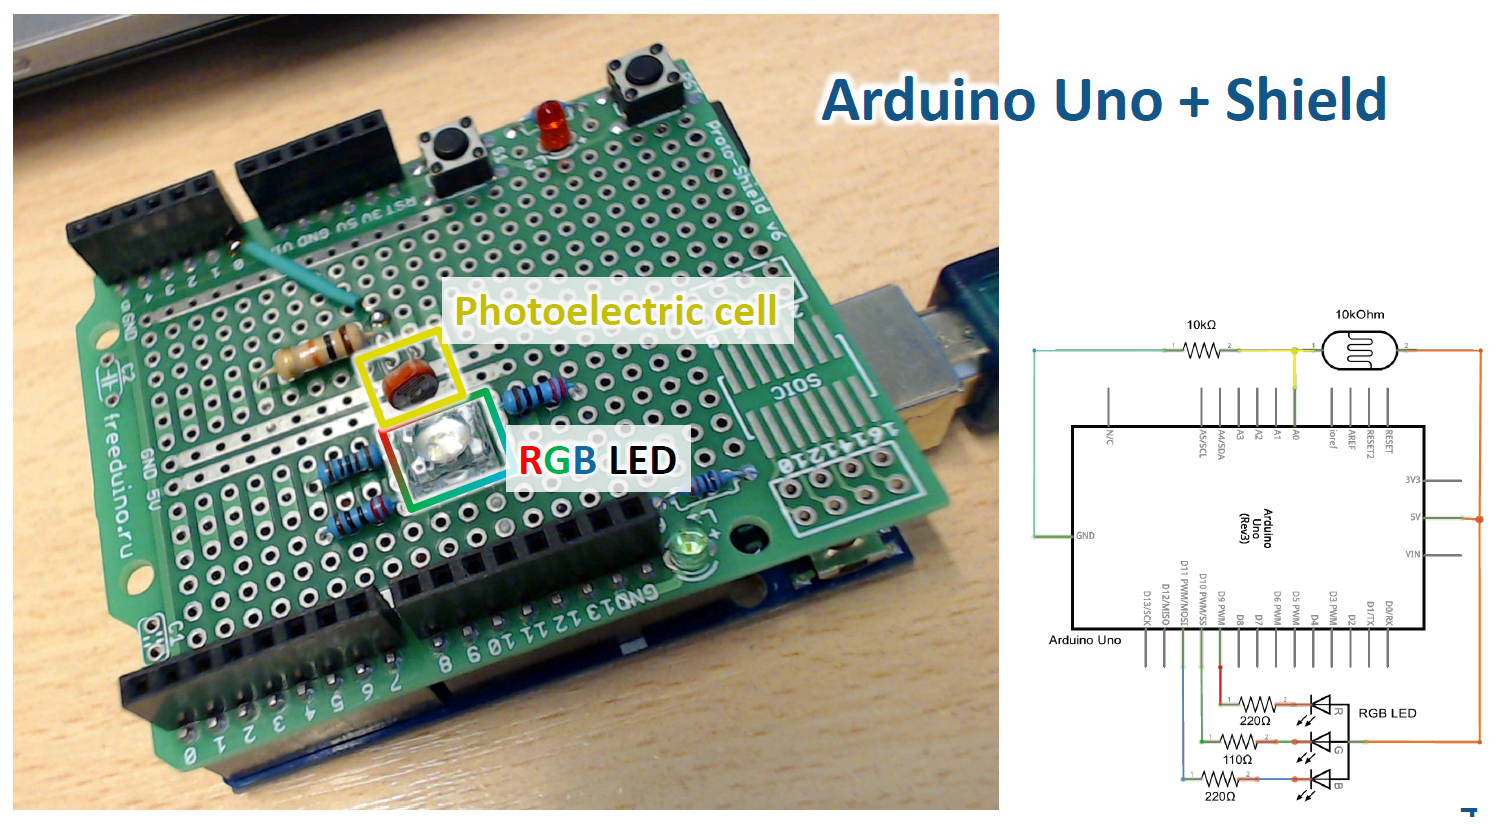

## Arduino Firmware

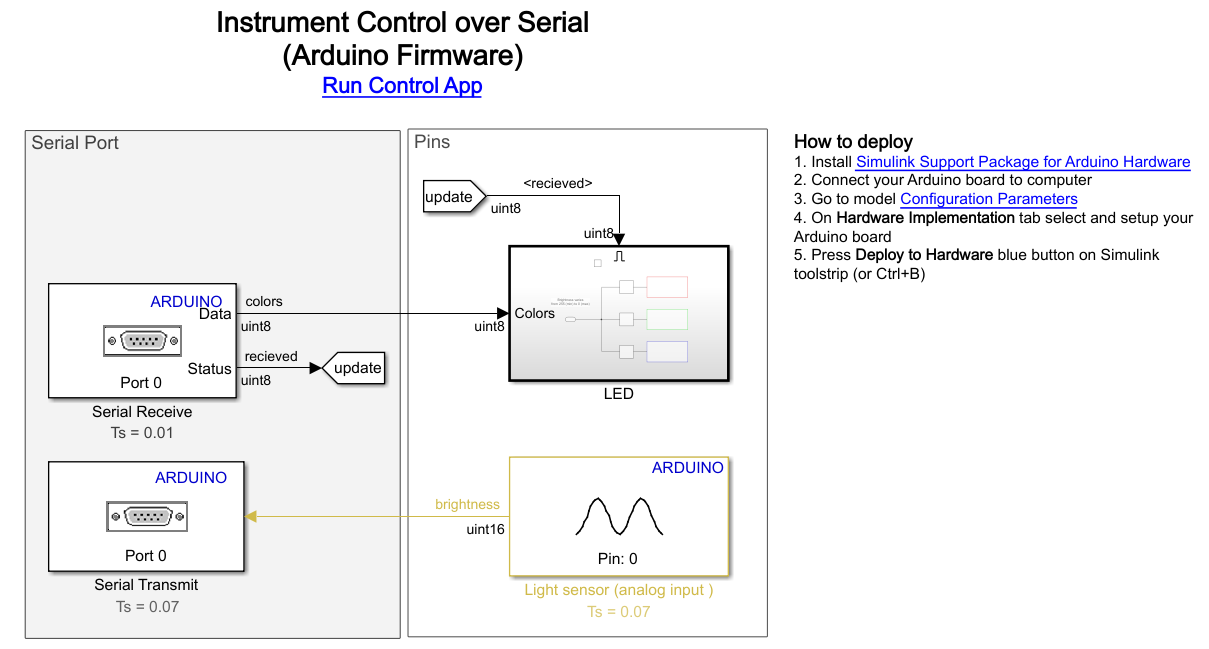

Open Arduino firmware model:

rgb_arduino

Follow **How to deploy** steps to deploy model to Arduino.

When Arduino has any data in input buffer it extracts RGB values from this data and rule an RGB led accordingly. At the same time Arduino reads light level from the sensor and sends this data to PC with a fixed time interval.

## Author

[**Pavel Roslovets**](https://roslovets.github.io) - Application Engineer at [ETMC Exponenta](https://exponenta.ru) (MathWorks distributor in Russia)